数据网格

例：画曲面 z=x^2+2y, 取x=[1,3,5]，y=[2,4,6]，应该有9个点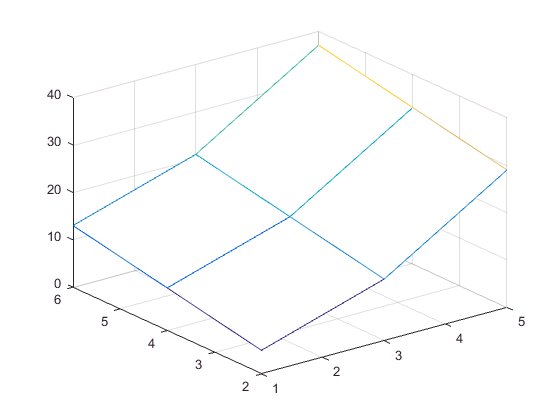

(1,2)  (3,2)  (5,2)      

(1,4)  (3,4)  (5,4)

(1,6)  (3,6)  (5,6)

x=[1 3 5];y=[2 4 6];
z=x.^2+2*y %直接运算不足以得出所有的结果
[X Y]=meshgrid(x,y)%使用数据网格拓展向量x和y
Z=X.^2+2*Y %现在可以直接运算了
mesh(X,Y,Z)%画图

基元列阵——不同性质数据混编

G={3,[1,2;3,5]; 'good' , 'sin(x)'}
G{1,1},G{1,2},G{2,1},G{2,2}
G{3}(1,2)%只有一个脚标则代表按列排列

结构数组——带有名称的基元列阵组成的数组

s=struct('type',{'big'},'color',{'red'},'x',{3,4})

s = 1x2 struct array with fields:

    type
    color
    x


s.x,s.color,s.type %按照域名输出

ans = 3

ans = 4

ans = red

ans = red

ans = big

ans = big

s(1),s(2)%输出每个域名的第某个元素

ans =      type: 'big'
    color: 'red'
        x: 3


ans =      type: 'big'
    color: 'red'
        x: 4
